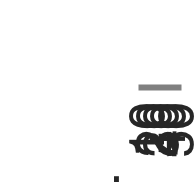

load dataAll21.mat
% dateAll is the dateset of 
% 1. infection averted (million)
% 2. time with baloxavir post sympotom onset  (0.5 for within 24h, 1 for 24-48 h, 2 for 0-48 h)
% 3. cases treated (%)
% 4. years studied
% 5. drug studied {1: 'No Drug', 2: 'Baloxavir', 3:'Oseltamivir'};
load popSize.mat  % number of indivudals in a simulation
load flu14to17.mat % used for weighted.
load N_uspop.mat % population of USA

YearTarget = 2017;
colorsValsBG = [0 0 0; 0 0.3 1; 0 1 0; ]; 
tempData = dataAll21( find(dataAll21(:,4)==YearTarget), :); 
OsizeLen = 1000;
OsizeNoDrug10 = tempData(1:OsizeLen,1)/popSize;
flu0809_Week = flu14to17(find(flu14to17(:,1)==YearTarget), 2);

NameDrug = {'No Drug', 'Baloxavir', 'Oseltamivir'};
iNDs = [2, 3];
medianPairs2 = [];
temp48s=[]; temp24s=[]; tempTs=[]; std24s=[]; std48s=[];
tempT48s = []; tempT24s=[]; temp24sa = []; temp48sa=[];
temp24_48s=[]; std24_48s = [];   temp48_72s=[]; std48_72s = [];
temp48us = []; std48us=[]; temp24us=[]; std24us=[]; temp24_48us=[]; std24_48us=[];
tempIndEpi = [3:2:11];% 10, 20, 30, 40, 50%

for i=1:length(iNDs)
    iND = iNDs(i);
    colorsVal = colorsValsBG(iND,:);
    temp48 = []; temp24 = []; tempT24=[]; tempT48=[];
    temp24_48=[]; std24_48 = []; temp48_72=[]; std48_72=[];
    temp48u = []; std48u =[];
    temp24u = []; std24u = [];
    temp24_48u=[]; std24_48u = []; 
    temp48a=[]; temp24a=[]; std48 = []; std24 =[]; 
    weight = sum(flu0809_Week)/10^4* N_uspop /10^6 /median(OsizeNoDrug10);
    
    for pVisit = (tempIndEpi-1)/2/10
        a = tempData( find(tempData(:,2) == 0.5 & tempData(:,3) == round(pVisit*100)/100 & tempData(:,5) == iND), 1) ;
        a = (OsizeNoDrug10(1:length(a)))*10^4-a;
        tempa = quantile( a*weight/10^4, [0.5, 0.25, 0.75]);
        temp48 = [temp48; tempa(1)]; 
        std48 = [std48; tempa([2,3])];
        
        a = tempData( find(tempData(:,2) == 1 & tempData(:,3) == round(pVisit*100)/100 & tempData(:,5) == iND), 1) ;
        a = (OsizeNoDrug10(1:length(a)))*10^4-a;
        tempa = quantile( a*weight/10^4, [0.5, 0.25, 0.75]);
        temp24 = [temp24; tempa(1)]; 
        std24 = [std24; tempa([2,3])];
        
        a = tempData( find(tempData(:,2) == 2 & tempData(:,3) == round(pVisit*100)/100 & tempData(:,5) == iND), 1) ;
        a = (OsizeNoDrug10(1:length(a)))*10^4-a;
        tempa = quantile( a*weight/10^4, [0.5, 0.25, 0.75]);
        temp24_48 = [temp24_48; tempa(1)]; 
        std24_48 = [std24_48; tempa([2,3])];
        
    end
    
    temp48s = [temp48s temp48];
    temp24s = [temp24s temp24];
    std48s = [std48s std48];
    std24s = [std24s std24];
    
    temp24_48s = [temp24_48s temp24_48];
    std24_48s = [std24_48s std24_48];
    
end


clf;
hold on;
rangeX = 1:1: (size(temp24s,1));


b = bar(rangeX*1.2, temp24_48s(rangeX,1), 0.2);
b(1).FaceColor =[0.6 0.7 1];

b = bar(rangeX*1.2+0.325, temp48s(rangeX,1), 0.2);
b(1).FaceColor = [0 0.3 1];

b = bar(rangeX*1.2-0.325, temp24s(rangeX,1), 0.2);
b(1).FaceColor =  7.5*[0.1 0.1 0.1]; 

[r,m,b] = regression([10:10:50],temp24s(:,1)');

xlim([0.5, 6.6])
xticks(1:1.25:6.6); xticklabels( [(tempIndEpi(1:end)-1)*5] );
xlabel({'Cases treated (%)', ' '})
ylabel({'Infections averted (millions)'})
box off;
set(gca, 'fontsize', 25);
set(gcf, 'PaperPositionMode', 'auto')
set(gcf, 'position', [0,0,100*5*1,61.8*5*1.5])

colorsVals = [0 0 0; 0.8 0.8 0.8; 0.5 0.5 0.5];
eb = errorbar(rangeX*1.2, temp24_48s(rangeX,1), temp24_48s(rangeX,1)-std24_48s(rangeX,1), -temp24_48s(rangeX,1)+std24_48s(rangeX,2),'.', 'Linewidth',3, 'color', colorsVals(3,:));
eb = errorbar(rangeX*1.2+0.325, temp48s(rangeX,1), temp48s(rangeX,1)-std48s(rangeX,1), -temp48s(rangeX,1)+std48s(rangeX,2),'.', 'Linewidth',3, 'color', colorsVals(3,:));
eb = errorbar(rangeX*1.2-0.325, temp24s(rangeX,1), temp24s(rangeX,1)-std24s(rangeX,1), -temp24s(rangeX,1)+std24s(rangeX,2),'.', 'Linewidth',3, 'color', colorsVals(3,:));
ylim([0 60])